Numerical Integral

Numerical Area under a curve

- cumsum (cumulative sum)--> tskes in  a vector of y values and gives back the area under

- the curve using rectangular Reman Sums

- cumsum - width of each rectangle is 1, thus area is given by y (height)

clear
clc
close all


figure
hold on

x = 1:4

x =      1     2     3     4


y = [1, 3, 2, 4]

y =      1     3     2     4


plot(x,y,'r.', 'markersize', 24)

inty = cumsum(y)

inty =      1     4     6    10


%inty --> [1 4 6 10] %last value is area under entire curve
plot(x,inty,'g.', 'markersize', 24)


cumtrapz - same as cumsum, but uses trapezodial approximation. 

- Takes in y and x because does not assume even spacing by 1. 

- Uses area of trapezoids to approx area under curve


inty = cumtrapz(x,y)

inty =          0    2.0000    4.5000    7.5000


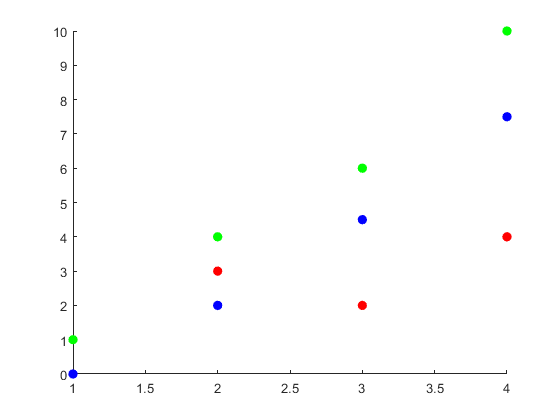

% inty --> [0, #, #, #]
plot(x,inty,'b.', 'markersize', 24)

trapz just returns total area under curve using trapezoidal method 

- (ie, the last nuber of vector returned by cumtrapz

Analytical Integral (power rule)

- 2*x^2 + 4*x + 5 ---> 2/3*x^3 + 4/2*x^2 + 5*x + C

- [2 4 5] ---> [2/3, 4/2, 5, C]

- Divide [2 4 5] by [3 2 1] --> [2/3, 4/2, 5, C]

integ =     0.6667    2.0000    5.0000         0


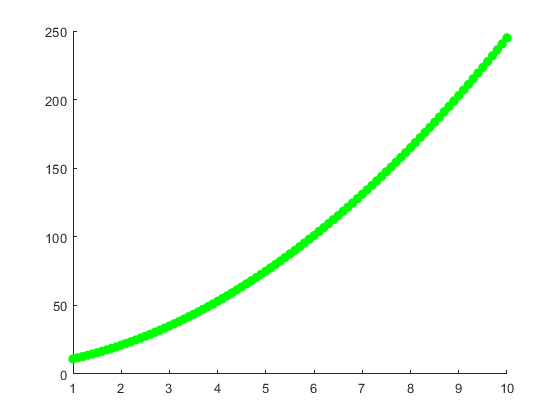

y =    11.0000   11.8200   12.6800   13.5800   14.5200   15.5000   16.5200   17.5800   18.6800   19.8200   21.0000   22.2200   23.4800   24.7800   26.1200   27.5000   28.9200   30.3800   31.8800   33.4200   35.0000   36.6200   38.2800   39.9800   41.7200   43.5000   45.3200   47.1800   49.0800   51.0200   53.0000   55.0200   57.0800   59.1800   61.3200   63.5000   65.7200   67.9800   70.2800   72.6200   75.0000   77.4200   79.8800   82.3800   84.9200   87.5000   90.1200   92.7800   95.4800   98.2200


newy =     7.6667    8.8073   10.0320   11.3447   12.7493   14.2500   15.8507   17.5553   19.3680   21.2927   23.3333   25.4940   27.7787   30.1913   32.7360   35.4167   38.2373   41.2020   44.3147   47.5793   51.0000   54.5807   58.3253   62.2380   66.3227   70.5833   75.0240   79.6487   84.4613   89.4660   94.6667  100.0673  105.6720  111.4847  117.5093  123.7500  130.2107  136.8953  143.8080  150.9527  158.3333  165.9540  173.8187  181.9313  190.2960  198.9167  207.7973  216.9420  226.3547  236.0393


figure
hold on
x = 1:.1:10;
coeffs = [2 4 5];
pow = length(coeffs) : -1 : 1;
newcoeffs = coeffs .* pow;
C = 0;
integ = [coeffs ./ (length(coeffs):-1:1) C]